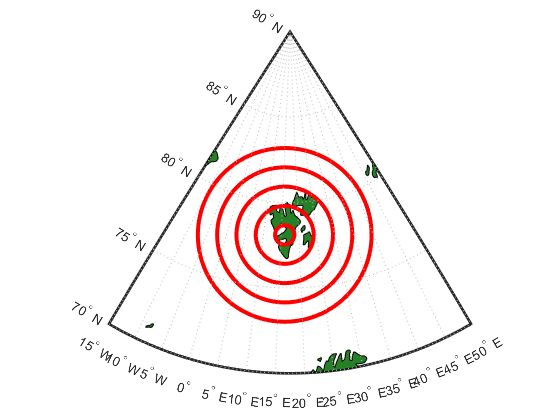

%%% topograph of Svalbard

worldmap([70 90], [-15 50])
load coastlines;
%plotm(coastlat, coastlon , "b")
geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
geoshow('worldcities.shp')
%geobubble(78.1,16.0)
circlem(78.1,16.0,r,'edgecolor', 'red', 'linewidth', 3)
hold off

%%% drawing the circles on cartesian coordinates

fpi_loc = [78.1, 16.0];
r = [62.82272976
188.4681893
314.1136488
439.7591083
565.4045678
];
N = [6,18,18,18,18];

circle(0,0,565.40,18)

ans =   handle to deleted Line


hold on
circle(0,0,439.75,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties


hold on
circle(0,0,314.11,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties


hold on
circle(0,0,188.46,6)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×60 double]
              YData: [1×60 double]
              ZData: [1×0 double]

  Show all properties


hold on 
circle(0,0,62.8,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


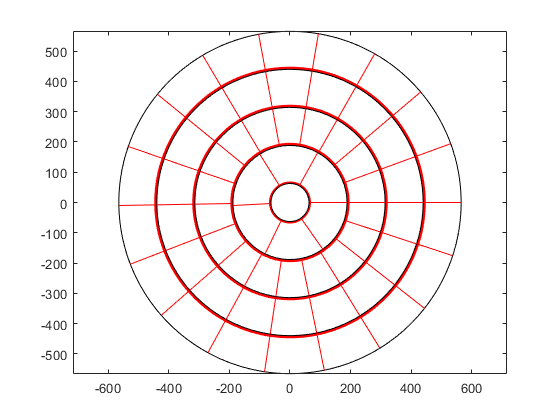

hold off

%%% projecting cartesian circles onto lat long coordinate system


worldmap([70 90], [-15 50])
geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
hold on
% circle(78.1, 16.0,565.40,18)
% hold on
% circle(78.1, 16.0,439.75,18)
% hold on
% circle(78.1, 16.0,314.11,18)
% hold on
% circle(78.1, 16.0,188.46,6)
% hold on 
circle(16.0,78.1, 62.8,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


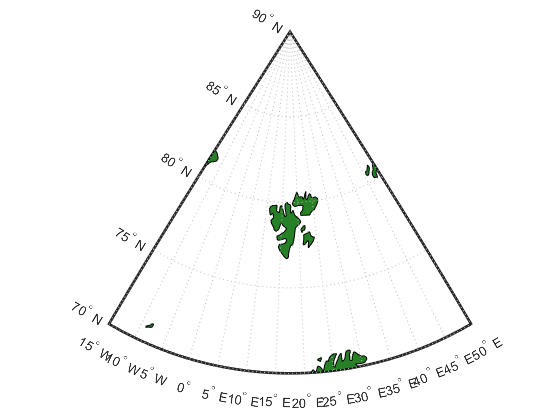

hold off

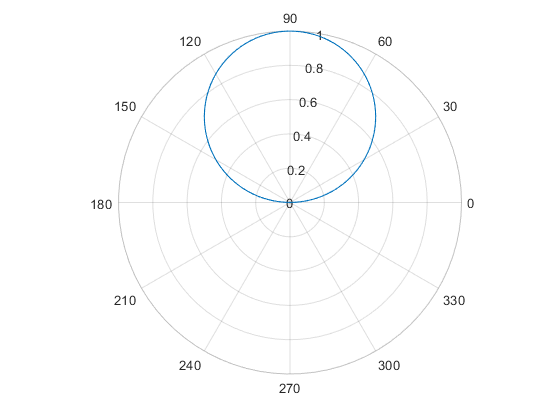

theta = linspace(0,2*pi);

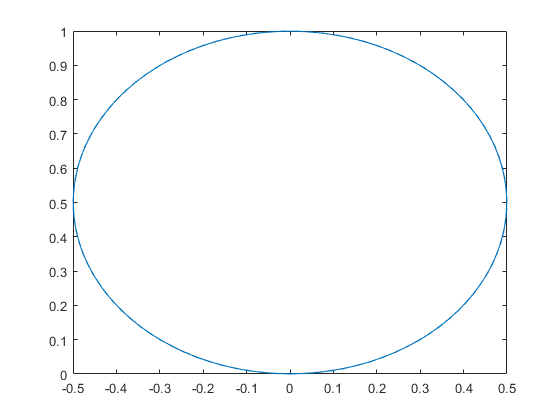

rho = 1*sin(theta);
polarplot(theta,rho)
[x,y] = pol2cart(theta,rho);
plot(x,y)

theta = deg2rad(14.1)

theta = 0.2461

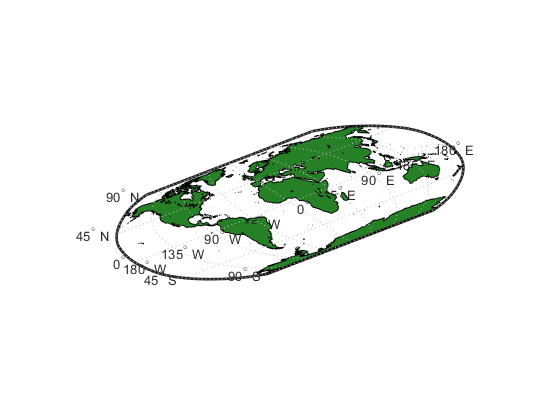

phi = linspace(-pi/2, pi/2);
[theta, phi] = meshgrid(theta, phi);
rho = 0.5;
[x,y,z] = sph2cart(theta,phi,rho);
plot3(x,y,z)
hold off

ax = worldmap("World")

ax =   Axes with properties:

             XLim: [-1.7050e+07 1.7050e+07]
             YLim: [-8.6500e+06 8.6500e+06]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


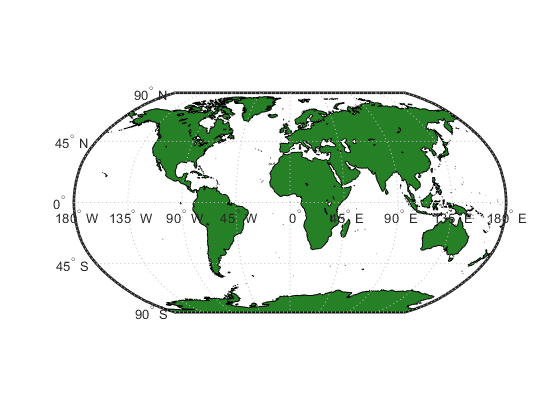

geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
hold on
a = linspace(0, 2*pi, 100);
xunits = r*cos(a) + 0;
yunits = r*sin(a) + 0;
plot(ax,xunits, yunits, 'Color', 'r', 'LineWidth', 3)
fill(xunits,yunits, "w");

load coastlines.mat;
[X,Y]= meshgrid(-179:180, -89:90);
plot(coastlon, coastlat,"r","LineWidth",2)
box on
hold on
circle(16.0,78.1, 62.8,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


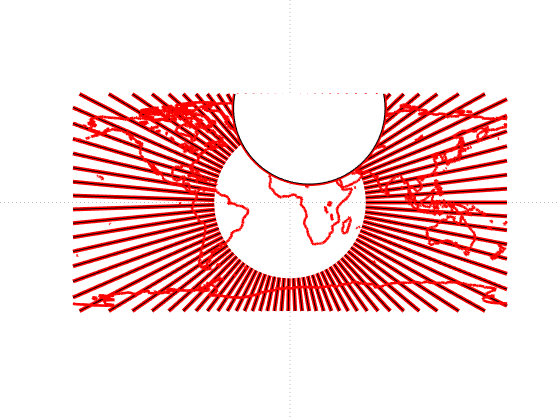

xlim([-180 180])
ylim([-90 90])
xlabel("longitude")
ylabel("latitude")
hold off


%% doesnt match because r in meters and lat lon should be in degrees !!


